t = -2*pi:0.1:2*pi;
A=256;
y_continua = A*sin(t);
% Graficamos la señal continua
figure;
disp 'señal continua figure 1'

señal continua figure 1


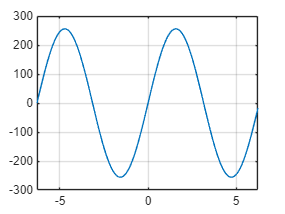

plot(t, y_continua);
grid on;

frecuencia = 1; 
cantidad_muestras = 100;
tiempo_discreto = 0:1:2*cantidad_muestras-1;
figure;
disp 'señal discreta figure 2'

señal discreta figure 2


senal_seno_discreta = A*sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras)

senal_seno_discreta =          0   16.0744   32.0853   47.9696   63.6646   79.1084   94.2399  108.9995  123.3289  137.1717  150.4730  163.1805  175.2441  186.6160  197.2514  207.1084  216.1479  224.3345  231.6357  238.0228  243.4705  247.9573  251.4655  253.9814  255.4948  256.0000  255.4948  253.9814  251.4655  247.9573  243.4705  238.0228  231.6357  224.3345  216.1479  207.1084  197.2514  186.6160  175.2441  163.1805  150.4730  137.1717  123.3289  108.9995   94.2399   79.1084   63.6646   47.9696   32.0853   16.0744


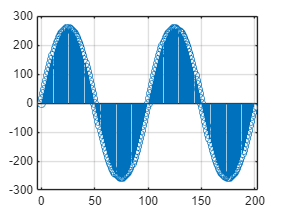

stem(tiempo_discreto, senal_seno_discreta);
grid on;

figure;
disp 'señal discreta cuantizada figure 3'

señal discreta cuantizada figure 3


senal_seno_discreta_Q = int8(A * sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras))

senal_seno_discreta_Q = 1×200 int8 row vector
     0    16    32    48    64    79    94   109   123   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   123   109    94    79    64    48    32    16


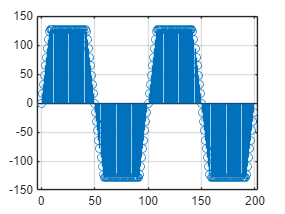

stem(tiempo_discreto, senal_seno_discreta_Q);
grid on;

figure
frecuencia = 1; 
tiempo_discreto = 0:1:2*cantidad_muestras-1; 
disp('señal discreta figure 4')

señal discreta figure 4


senal_seno_discreta_Q1 = round(A * sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras),1)

senal_seno_discreta_Q1 =          0   16.1000   32.1000   48.0000   63.7000   79.1000   94.2000  109.0000  123.3000  137.2000  150.5000  163.2000  175.2000  186.6000  197.3000  207.1000  216.1000  224.3000  231.6000  238.0000  243.5000  248.0000  251.5000  254.0000  255.5000  256.0000  255.5000  254.0000  251.5000  248.0000  243.5000  238.0000  231.6000  224.3000  216.1000  207.1000  197.3000  186.6000  175.2000  163.2000  150.5000  137.2000  123.3000  109.0000   94.2000   79.1000   63.7000   48.0000   32.1000   16.1000


stem(tiempo_discreto, senal_seno_discreta_Q1);
grid on;

Espacio disponible para diseñar un algoritmo que permita calcular y graficar el error de cuantización para las figuras 2, 3 y 4 en comparación con la figura 2.


e =          0   -0.0256   -0.0147   -0.0304   -0.0354    0.0084    0.0399   -0.0005    0.0289   -0.0283   -0.0270   -0.0195    0.0441    0.0160   -0.0486    0.0084    0.0479    0.0345    0.0357    0.0228   -0.0295   -0.0427   -0.0345   -0.0186   -0.0052         0   -0.0052   -0.0186   -0.0345   -0.0427   -0.0295    0.0228    0.0357    0.0345    0.0479    0.0084   -0.0486    0.0160    0.0441   -0.0195   -0.0270   -0.0283    0.0289   -0.0005    0.0399    0.0084   -0.0354   -0.0304   -0.0147   -0.0256


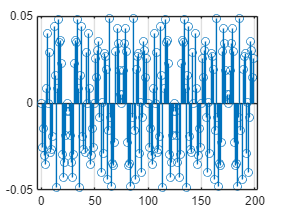

disp 'Espacio disponible para diseñar un algoritmo que permita calcular y graficar el error de cuantización para las figuras 2, 3 y 4 en comparación con la figura 2.'